## 初期化

cd(fileparts(matlab.desktop.editor.getActiveFilename)) % このmlxファイルがある場所に自動的に移動
clc
clear
close all

## シミュレーション条件

ts = 0.01;
fs = 10;

## Reference

y_d = 0.2;

## Position Controller

K_p = diag([1,1]);
alpha = 2;
obst = "without_window";
umax = [4;4];
umin = [-4;-4];

## Attitude Controller

k_R = 2;
k_theta = 3;

## Kinematics

eta_0 = [0;0];
p_0 = [0;0];
% theta_d = 10*pi/180;
theta_d = 0;

sim_action = 1;
    
if sim_action == 1  
    out = sim("kinematics_model.slx");
end

## データの整理

position = out.logsout.getElement('position').Values;
p_d = out.logsout.getElement('p_d').Values;
attitude = out.logsout.getElement('attitude').Values;
desired_attitude = out.logsout.getElement('desired_attitude').Values;
velocity= out.logsout.getElement('velocity').Values;
angular_velocity = out.logsout.getElement('angular_velocity').Values;
figpath = 'figs';

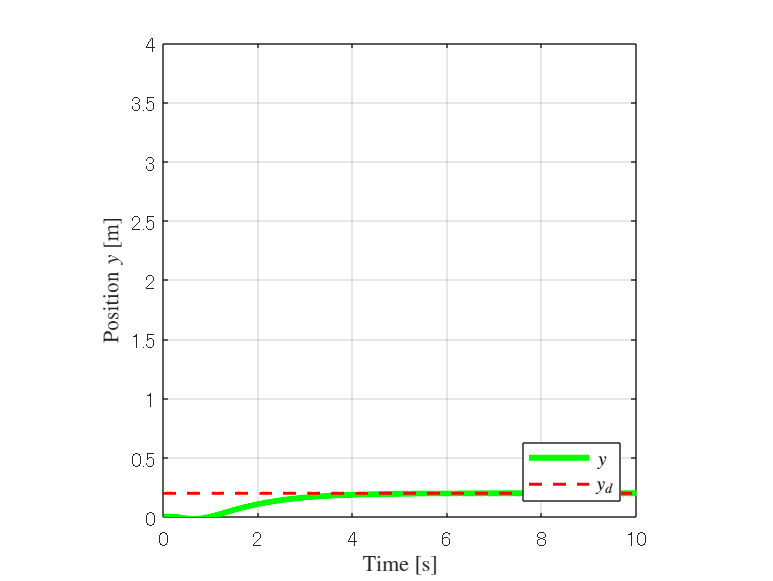

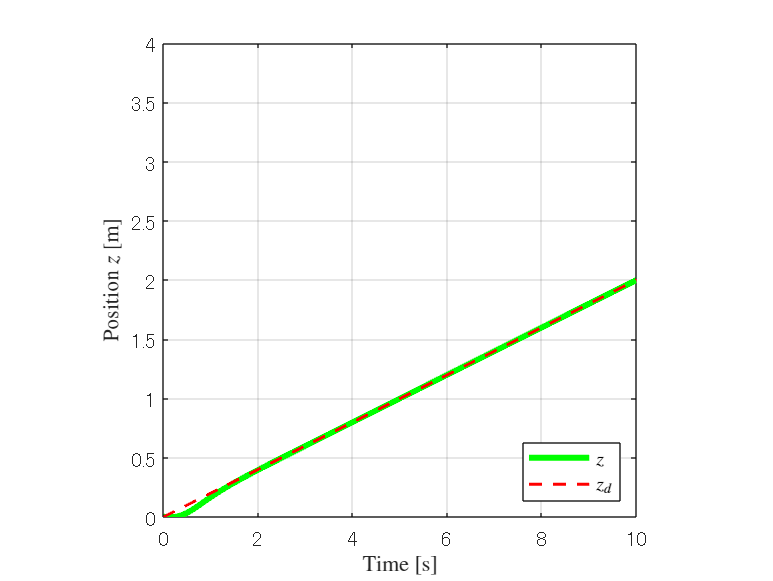

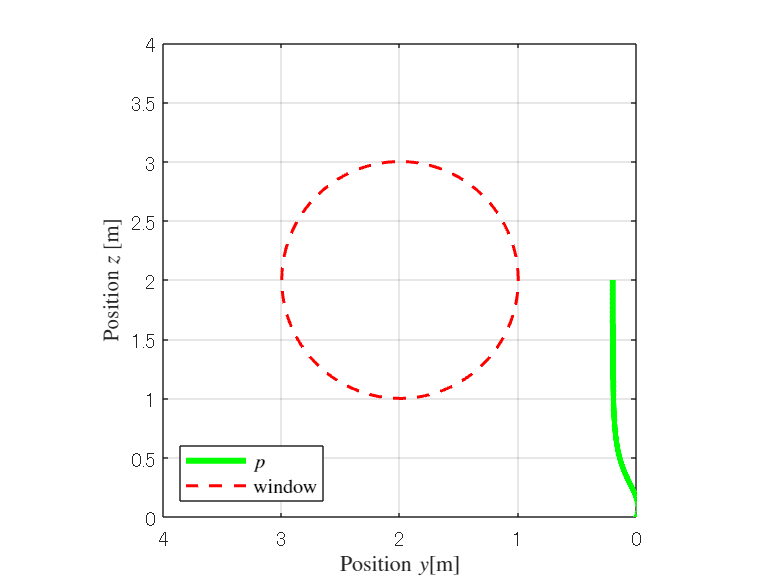

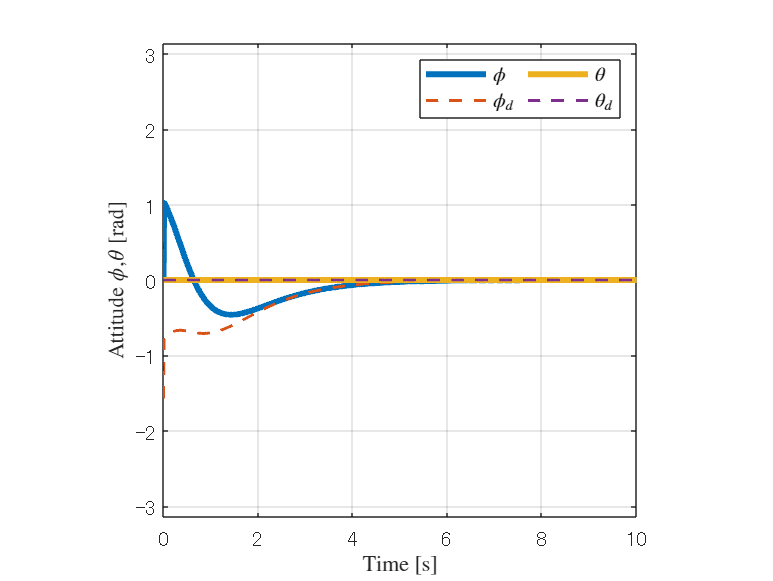

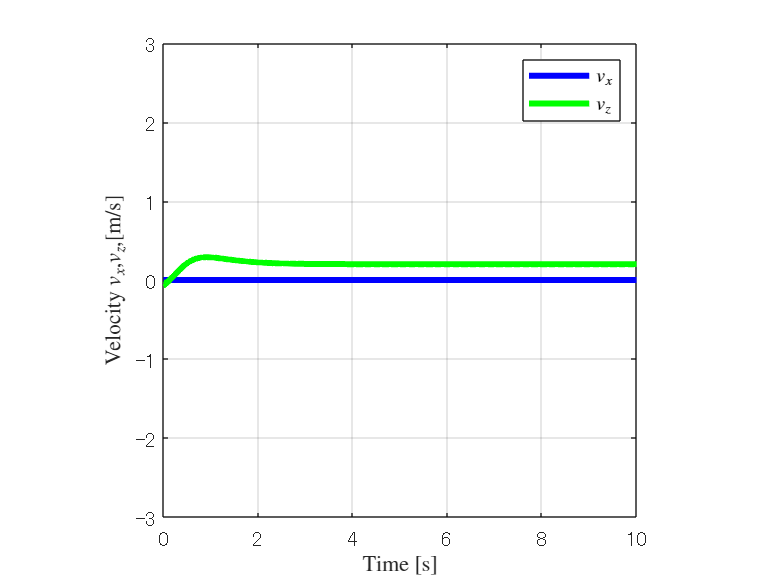

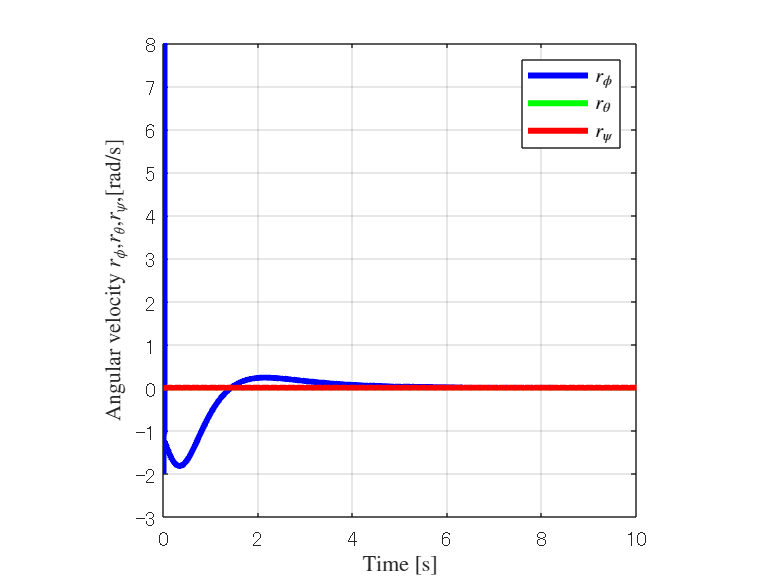

dataplot_action = 1;
if dataplot_action == 1
    run("data_plot.mlx")
end

## アニメーション

tree = {
    @shape.cylinder {
        ':id', 'motor1';
        ':scale', [0.015 0.03 0.03];
        ':transform', { 'translate', [1 1 0], 'yrotate', -1.5708, 'xrotate', 3.927 };
        'FaceVertexCData', [0.3 0.3 0.3];
        @shape.cylinder {
            ':id', 'motoraxis1';
            ':scale', [0.015 0.01 0.01];
            'FaceVertexCData', [0.8 0.8 0.8];
            @shape.box {
                ':id', 'prop1_1';
                ':scale', [0.015 0.06 0.002];
                ':transform', { 'translate', [-0.005 0.03 0], 'yrotate', -1.2566 };
                'FaceVertexCData', [0 1 0];
            }
            @shape.box {
                ':id', 'prop1_2';
                ':scale', [0.015 0.06 0.002];
                ':transform', { 'translate', [-0.005 -0.03 0], 'yrotate', 1.2566 };
                'FaceVertexCData', [0 1 0];
            }
        }
    }
}
tree = {
    @shape.cylinder {
        ':id', 'wheel1';
        ':scale', [0.02 0.3 0.3];
        ':transform', { 'transl

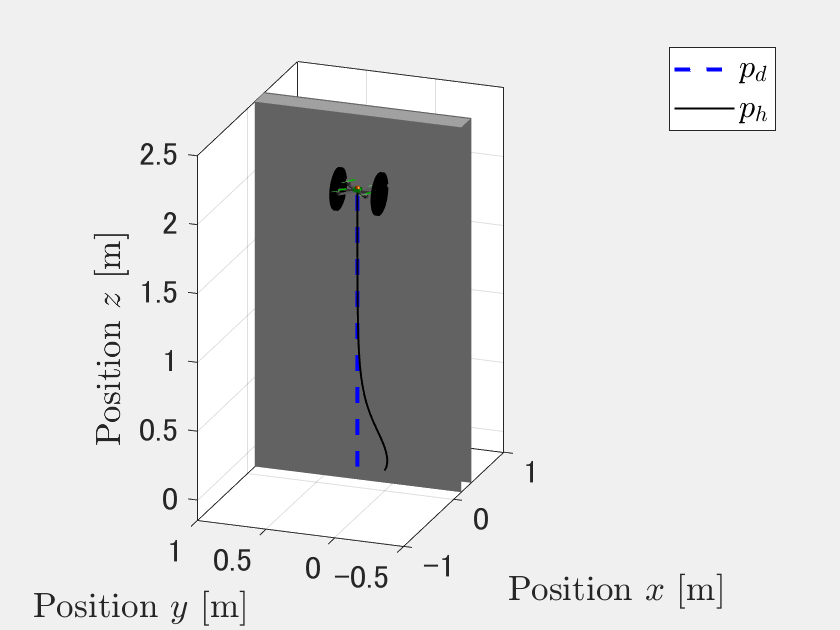

経過時間は 28.717813 秒です。


animation_unicycle = 1;
if animation_unicycle == 1
    run("animation.mlx")
end